Iteration 1: Best Cost = 1.7454
Iteration 2: Best Cost = 1.6597
Iteration 3: Best Cost = 1.6597


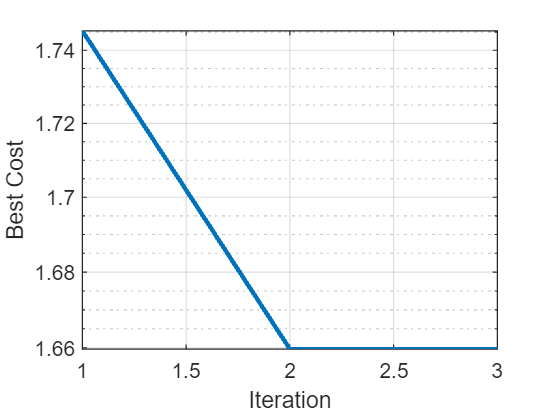

clc
clear
close all
%%minimization code for the classification network%%
%% parameters
rng default % For reproducibility
n=10; k=2; q=2; l=n+1;
%states to discriminate from%%
gammain=1;%dephasing rate for Vins%
gammadep=0;%dephasing rate%
gammaout=zeros(q,1);
gammaout(1)=1;%dephasing rate for Vouts%;%assuring normalization%
gammaout(2)=1;
% gammaout(3)=1;
% gammaout(4)=1;
%states to discriminate from%%
csi(1,:)=sqrt(1/2)*[1 1];
csi(2,:)=sqrt(1/2)*[1 -1];
%% Problem Definition
CostFunction = @(H)parallelCF(H,k,n,q,gammain,gammadep,gammaout,csi);        % Cost Function. the wanted output we want to extract is the vectorized Hamiltonian
nVar = n^2;            % Number of Decision Variables
VarSize = [1 nVar];   % Size of Decision Variables Matrix
VarMin =-200;         % Lower Bound of Variables
VarMax = 200;         % Upper Bound of Variables
%% PSO Parameters
MaxIt = 500;      % Maximum Number of Iterations
nPop = 150;        % Population Size (Swarm Size)
% PSO Parameters
w=1;            % Inertia Weight
wdamp=0.99;     % Inertia Weight Damping Ratio
c1=2.0;         % Personal Learning Coefficient
c2=0.9;         % Global Learning Coefficient
% Velocity Limits
VelMax=0.1*(VarMax-VarMin); %also a parameter, forming the velocity of the particles. changes each iteration
VelMin=-VelMax;
% addition of Hamiltonians Memory %
HamiltonianMemory = false;
% ICF(rand(1,n^2),k,n,q,gammain,gammadep,gammaout,csi)
H=PSO(CostFunction,VarSize,VarMin,VarMax,MaxIt,nPop,w,wdamp,c1,c2,VelMax,VelMin,HamiltonianMemory);